# First part of the challenge

## Step 0

%% F1013B - Challenge - Diagnosis of malaria
clc;
close all; 
clear;


%% Step 0

v = 0.5; % Variable for the position in 3D space
dx = -1; % Variable to move the vertex
dy = 0;  % Variable to move the vertex
dz = 0;  % Variable to move the vertex

largo = 3;  % length of the red plate de la lámina roja
largo2 = 3; % length of the blue plate
ancho = -0.2; 
alto = 1;

% Define vertices for rectangle 1 (red)
 vertices = [-v*ancho+dx  -v*largo+dy  -v+dz;  %v1
             -v*ancho+dx   v*largo+dy  -v+dz;  %v2
              v*ancho+dx   v*largo+dy  -v+dz;  %v3 
              v*ancho+dx  -v*largo+dy  -v+dz;  %v4
             -v*ancho+dx  -v*largo+dy   v+dz;  %v5
             -v*ancho+dx   v*largo+dy   v+dz;  %v6
              v*ancho+dx   v*largo+dy   v+dz;  %v7
              v*ancho+dx  -v*largo+dy   v+dz]; %v8
 
% Define the polygon (patch) usando the vertices previously defined
caras = [  % complete code
    1 2 3 4; % Bottom face
    5 6 7 8; % Top face
    2 3 7 6; % Front face
    4 1 5 8; % Back face
    1 2 6 5; % Left face
    3 4 8 7; % Right face
 ];
 
% Define vertices for rectangle 2 (blue)
vertices2 = [-v*ancho+1  -v*largo+dy  -v+dz;  %v1
             -v*ancho+1   v*largo+dy  -v+dz;  %v2
              v*ancho+1   v*largo+dy  -v+dz;  %v3 
              v*ancho+1  -v*largo+dy  -v+dz;  %v4
             -v*ancho+1  -v*largo+dy   v+dz;  %v5
             -v*ancho+1   v*largo+dy   v+dz;  %v6
              v*ancho+1   v*largo+dy   v+dz;  %v7
              v*ancho+1  -v*largo+dy   v+dz]; %v8
         
% Define the polygon (patch) usando the vertices previously defined
caras2 = [  % complete code
    1 2 3 4;  % Bottom face
    5 6 7 8;  % Top face
    1 2 6 5;  % Left face
    2 3 7 6;  % Front face
    3 4 8 7;  % Right face
    4 1 5 8   % Back face
];    

% Specify the polygons using patch
hold on;
patch('Vertices', vertices, 'Faces', caras, 'FaceColor', 'r', 'EdgeColor', 'k'); % Red plate
patch('Vertices', vertices2, 'Faces', caras2, 'FaceColor', 'b', 'EdgeColor', 'k'); % Blue plate

axis([-2 2 -2 2 -2 2]); % scale axes
view(30,30); % view the angle


## Step 1


%% Step 1
% The goal of this section is to simply plot a meshgrid around the parallel
% plates, in such a way that includes the interior and exterior of them
% Hint: use the functions mesh grid and plot

% create the mesh
x0 = -2;
x1 = 2;
y0 = -2;
y1 = 2;  
nx = 0.5;
ny = 0.5;
       
[xGrid, yGrid] = meshgrid(x0:nx:x1, y0:ny:y1); % mesh parametrization % complete code here
zGrid = xGrid * 0; % for completenes we create a parameter for z, but we make it zero

% plot
plot(xGrid,yGrid,'.b');


## Step 2

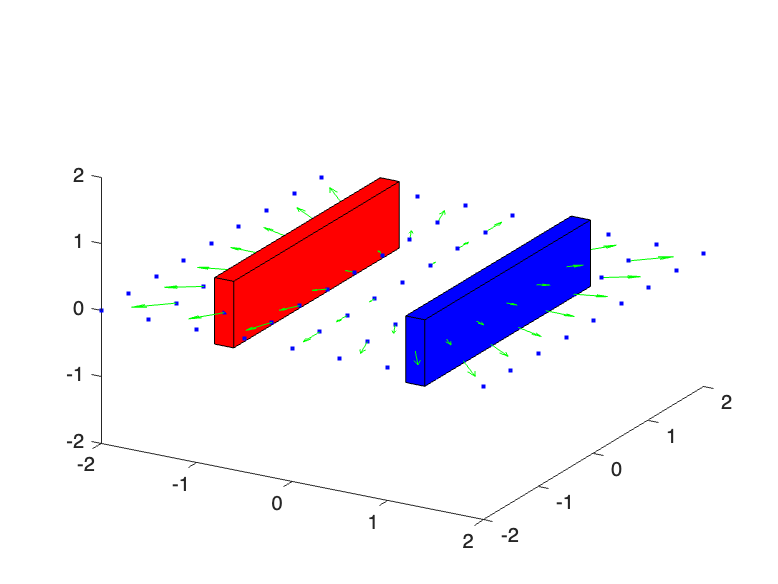

%% Step 2: Add a vector field and plot
% Hint: use the function quiver3
% complete code here
h = quiver3(xGrid, yGrid, zGrid, xGrid, yGrid, zGrid, 'g');

hold on;

# Second part of the challenge

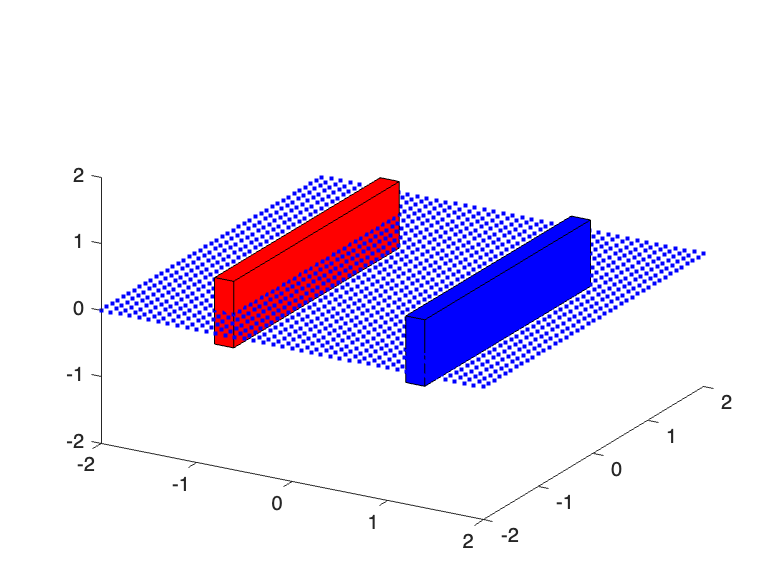

% First red-raw the plates and comment the lines (like above)
cla; 
clear;
close all;

v = 0.5; % 

dx = -1; % 
dy = 0;  % 
dz = 0;  % 

largo = 3;  % 
largo2 = 3; % 
ancho = -0.2;
alto = 1;

% Define vertices for rectangle 1 (red)
vertices = [-v*ancho+dx  -v*largo+dy  -v+dz;  %v1
             -v*ancho+dx   v*largo+dy  -v+dz;  %v2
              v*ancho+dx   v*largo+dy  -v+dz;  %v3 
              v*ancho+dx  -v*largo+dy  -v+dz;  %v4
             -v*ancho+dx  -v*largo+dy   v+dz;  %v5
             -v*ancho+dx   v*largo+dy   v+dz;  %v6
              v*ancho+dx   v*largo+dy   v+dz;  %v7
              v*ancho+dx  -v*largo+dy   v+dz]; %v8
 
% Define the polygon (patch) usando the vertices previously defined 
caras = [  % complete code
    1 2 3 4; % Bottom face
    5 6 7 8; % top face
    1 2 6 5; % Front face
    2 3 7 6; % Right face
    3 4 8 7; % Back face
    4 1 5 8 % Left face
];
 
% Define vertices for rectangle 2 (blue)
vertices2 = [-v*ancho+dx + 2  -v*largo+dy  -v+dz;  %v1
             -v*ancho+dx + 2  v*largo+dy  -v+dz;  %v2
              v*ancho+dx + 2  v*largo+dy  -v+dz;  %v3 
              v*ancho+dx + 2 -v*largo+dy  -v+dz;  %v4
             -v*ancho+dx + 2 -v*largo+dy   v+dz;  %v5
             -v*ancho+dx + 2  v*largo+dy   v+dz;  %v6
              v*ancho+dx + 2  v*largo+dy   v+dz;  %v7
              v*ancho+dx + 2 -v*largo+dy   v+dz]; %v8
         
% Define the polygon (patch) usando the vertices previously defined
caras2 = [  % complete code
    1 2 3 4; % Bottom face
    5 6 7 8; % top face
    1 2 6 5; % Front face
    2 3 7 6; % Right face
    3 4 8 7; % Back face
    4 1 5 8 % Left face
];      

% plot
% Specify the polygons using patch
hold on;
patch('Vertices', vertices, 'Faces', caras, 'FaceColor', 'r', 'EdgeColor', 'k'); % Red plate
patch('Vertices', vertices2, 'Faces', caras2, 'FaceColor', 'b', 'EdgeColor', 'k'); % Blue plate


axis([-2 2 -2 2 -2 2]); % 
view(30,30); % 


%@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@
%@@@@@@  Principle of superposition                               @@@@@@
%@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@

% mesh creation
x0 = -2;
x1 = 2;
y0 = -2;
y1 = 2;  
nx = 0.1; % make resolution finer to ease the visualization
ny = 0.1;
       
[xGrid, yGrid] = meshgrid(x0:nx:x1, y0:ny:y1); % mesh parametrization % complete code here
zGrid = xGrid * 0; % for completenes we create a parameter for z, but we make it zero


% plot grid
plot(xGrid,yGrid,'.b');

## **Now charges will appear!**

**First charge**


% Negative 1 (blue plate)
Qn1 = -20; % Negative charge on the blue surface
eps0 = 8.854e-12;  % Dielectric constant of the media
k = 1/(4*pi*eps0); % Electric constant
Rxn1 = xGrid - (1); % % Distance in x from charge
Ryn1 = yGrid - (-largo2/2); % % Distance in y from charge
Rzn1 = zGrid;% - 0.5;     % Distance in z from charge

% Calculation of the field from a single charge 
% E = k * (qr / r^3)
% R = distance between the charges

R1 = sqrt(Rxn1.^2 + Ryn1.^2 + Rzn1.^2);
Ex1 = k * Qn1 * (Rxn1 ./ R1.^3);
Ey1 = k * Qn1 * (Ryn1 ./ R1.^3);
Ez1 = k * Qn1 * (Rzn1 ./ R1.^3);
E1 = sqrt(Ex1.^2 + Ey1.^2 + Ez1.^2);


**Second charge (when adding the field remember the superposition principle!!!!)**

% Second charge (when adding the field remember the superposition principle!!!!)
% Positive charge 1 (red plate)
Qp1 = 20; 
Rxp1 = xGrid - (-1); % Distance in x from charge
Ryp1 = yGrid - (-1.5); % Distance in y from charge
Rzp1 = zGrid; % Distance in z from charge

% Calculation of the field from a single charge 
% E = k * (qr / r^3)
% R = distance between the charges
R2 = sqrt(Rxp1.^2 + Ryp1.^2 + Rzp1.^2);
Ex2 = k * Qp1 * (Rxp1 ./ R2.^3);
Ey2 = k * Qp1 * (Ryp1 ./ R2.^3);
Ez2 = k * Qp1 * (Rzp1 ./ R2.^3);
E2 = sqrt(Ex2.^2 + Ey2.^2 + Ez2.^2);

**Third charge (when adding the field remember the superposition principle!!!!!!!!!!!!!!!!!!)**

% Negative charge 2 (third charge)
Qn2 = -20; % Negative Charge
Rxn2 = xGrid - (1); % Distance in x from the charge
Ryn2 = yGrid - (largo2 / 2); % Distance in y from the charge
Rzn2 = zGrid - 0.5; % Distance in z from charge

R3 = sqrt(Rxn2.^2 + Ryn2.^2 + Rzn2.^2);
Ex3 = k * Qn2 * (Rxn2 ./ R3.^3);
Ey3 = k * Qn2 * (Ryn2 ./ R3.^3);
Ez3 = k * Qn2 * (Rzn2 ./ R3.^3);
E3 = sqrt(Ex3.^2 + Ey3.^2 + Ez3.^2);

**Fourth charge (when adding the field remember the superposition principle!!!!!!!!!!!!!!!!!!)**

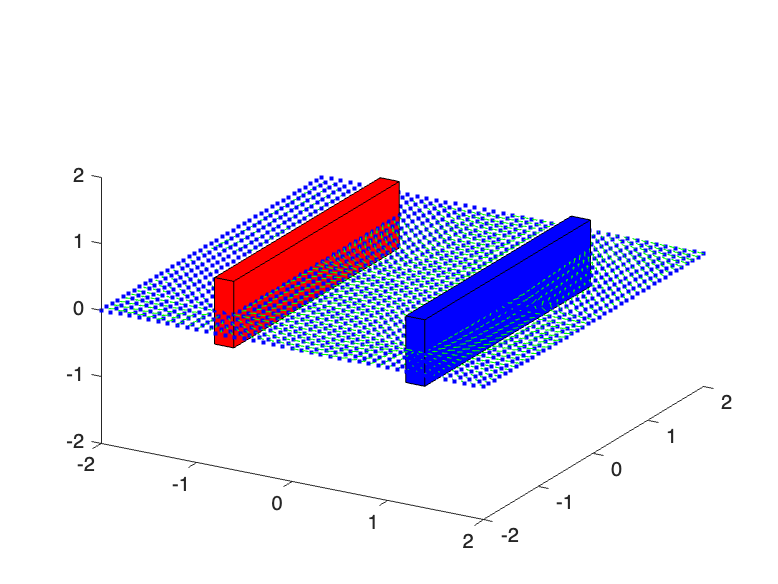

% Positive charge 2 (fourth charge)
Qp2 = 20; % Positive charge
Rxp2 = xGrid - (-1); % Distance in x from charge
Ryp2 = yGrid - (1.5); % Distance in y from charge
Rzp2 = zGrid - 0.5; % Distance in z from charge

% Calculate the electric field from the fourth charge
R4 = sqrt(Rxp2.^2 + Ryp2.^2 + Rzp2.^2);
Ex4 = k * Qp2 * (Rxp2 ./ R4.^3);
Ey4 = k * Qp2 * (Ryp2 ./ R4.^3);
Ez4 = k * Qp2 * (Rzp2 ./ R4.^3);
E4 = sqrt(Ex4.^2 + Ey4.^2 + Ez4.^2);
 
% Cargas totales 
Rtot = R1 + R2 + R3 + R4;
Extot = Ex1 + Ex2 +  Ex3 + Ex4;
Eytot = Ey1 + Ey2 + Ey3 + Ey4;
Eztot = Ez1 + Ez2 + Ez3 + Ez4;
Etot = sqrt(Extot.^2 + Eytot.^2 + Eztot.^2);

% normalize the vector components by dividing by E
i = Extot ./ Etot;
j = Eytot ./ Etot;
k = Eztot ./ Etot;


% plot [Hint: use quiver3 as the previous stage]
% This should be the complete plot
quiver3(xGrid, yGrid, zGrid, i, j, k, 0.5, 'g');